# 测试（间接法）

clc
clear
close all
addpath("src\");

## C-W交会

tf = 2000.; % s
x0 = [2200., 8000., 1000., 0., 0., 0.]';  % km, km/s
xf = zeros(6, 1);
p.n = 0.00111; % rad/s
p.tspan = 1; % s
p.f = 0.01; % N/kg; m/s^2

### 能量最优

@CostEnergy: $\int ||{\bf{u}}||^2 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    0.000000e+00    1.279e+04    4.263e-14
    1      14    9.824538e-02    1.544e+03    1.505e+04    1.113e-02
    2      21    8.491502e-02    1.737e-06    2.167e+04    2.326e-03


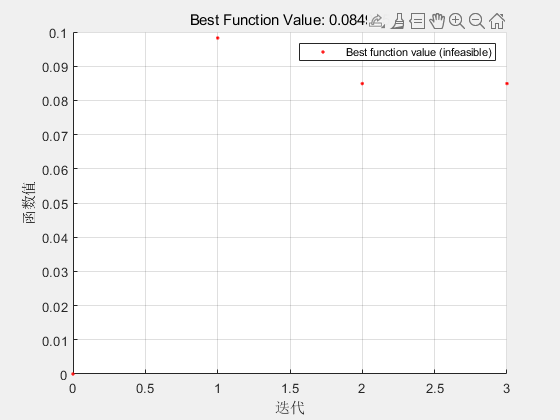


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[s,fval,exitflag,output] = IndirOptEnergy(@CwEnergyOpt, x0, xf, tf, p);

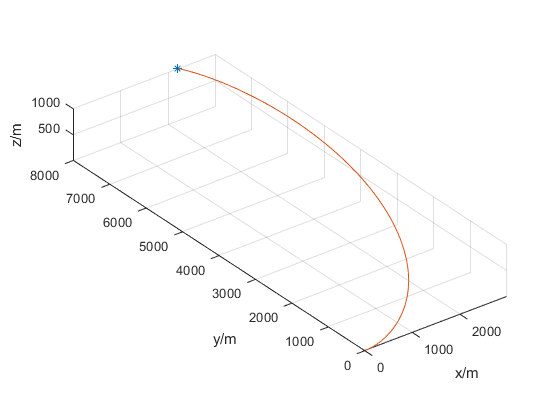

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

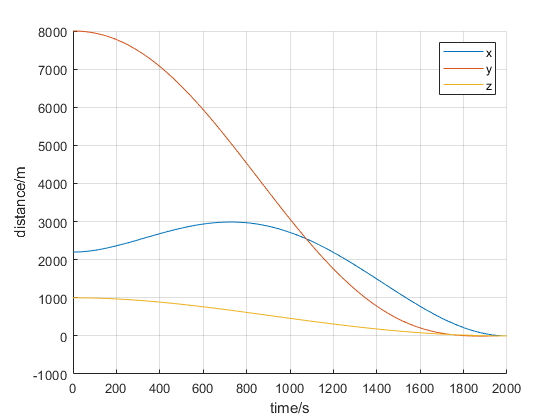

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

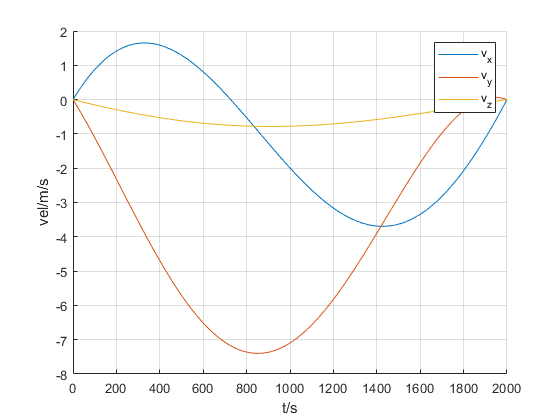

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

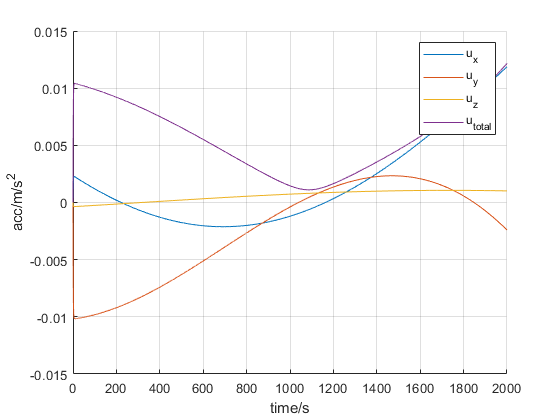

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 时间最优

@CostEnergy: $\int 1 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       8    2.000000e+03    3.441e+03    1.000e+00
    1      16    2.000000e+03    3.435e+03    1.000e+00    1.520e+00


    2      24    1.997492e+03    1.590e+03    1.000e+00    2.583e+00


    3      32    1.997495e+03    1.589e+03    1.000e+00    4.640e-02
    4      40    1.997489e+03    8.839e+02    1.000e+00    2.669e-01
    5      48    1.997573e+03    8.836e+02    1.000e+00    2.370e-01
    6      56    1.996674e+03    8.407e+02    1.000e+00    9.024e-01


    7      64    1.995469e+03    8.319e+02    1.000e+00    1.205e+00


    8      72    1.993508e+03    8.385e+02    1.000e+00    1.960e+00


    9      80    1.991876e+03    8.541e+02    1.000e+00    1.633e+00


   10      88    1.989349e+03    8.525e+02    1.000e+00    2.528e+00
   11      96    1.982546e+03    8.623e+02    1.000e+00    6.803e+00
   12     104    1.966344e+03    8.559e+02    1.000e+00    1.620e+01
   13     112    1.891886e+03    8.282e+02    1.000e+00    7.446e+01
   14     120    1.611800e+03    6.887e+02    1.000e+00    2.801e+02


   15     128    1.611872e+03    6.886e+02    1.000e+00    1.032e-01


   16     136    1.583933e+03    3.910e+02    1.000e+00    2.796e+01
   17     144    1.380843e+03    3.221e+02    9.999e-01    2.031e+02


   18     153    1.379724e+03    3.213e+02    9.999e-01    1.121e+00
   19     166    1.372539e+03    3.139e+02    1.000e+00    7.196e+00
   20     174    1.372693e+03    3.138e+02    1.000e+00    1.538e-01
   21     182    1.372652e+03    1.618e+02    1.000e+00    5.746e-02
   22     190    1.371878e+03    1.022e+02    9.999e-01    8.060e-01
   23     202    1.371526e+03    1.033e+02    9.999e-01    4.371e-01
   24     210    1.367510e+03    5.613e+01    1.000e+00    4.045e+00
   25     218    1.338739e+03    2.725e+01    1.000e+00    2.877e+01
   26     227    1.335485e+03    2.144e+01    1.000e+00    3.263e+00
   27     235    1.333348e+03    1.909e+01    1.000e+00    2.137e+00
   28     243    1.332503e+03    1.813e+01    1.000e+00    8.452e-01
   29     251    1.332123e+03    2.209e+01    1.000e+00    3.801e-01
   30     259    1.328678e+03    1.442e+01    1.000e+00    3.444e+00
                                            First-order      Norm of
 Iter F-count            f(x)  Fea

   35     321    1.304001e+03    1.117e+01    1.000e+00    6.860e-03
   36     335    1.304000e+03    1.117e+01    1.000e+00    7.521e-04
   37     352    1.304000e+03    1.117e+01    1.000e+00    1.643e-04
   38     369    1.304000e+03    1.117e+01    1.000e+00    3.593e-05
   39     388    1.304000e+03    1.117e+01    1.000e+00    1.964e-06
   40     403    1.304000e+03    1.117e+01    1.000e+00    1.719e-06
   41     423    1.304000e+03    1.117e+01    1.000e+00    4.698e-08
   42     432    1.304000e+03    1.117e+01    1.000e+00    9.652e-09


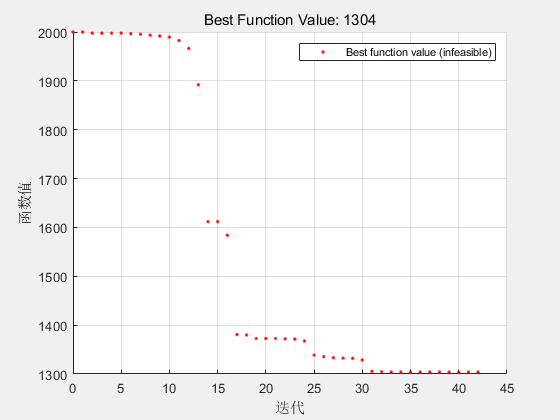


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



[s,fval,exitflag,output] = IndirOptTime(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p);

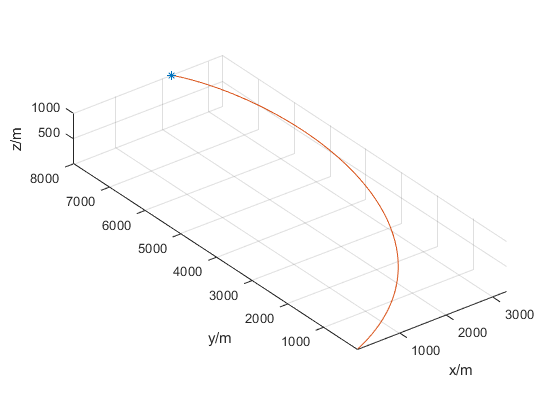

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

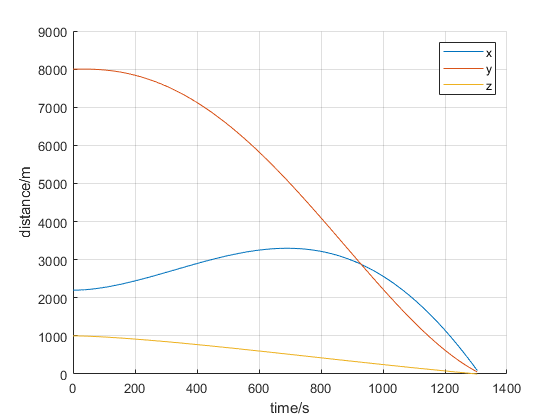

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

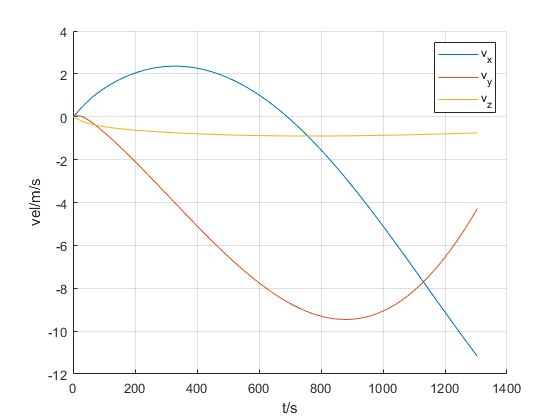

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

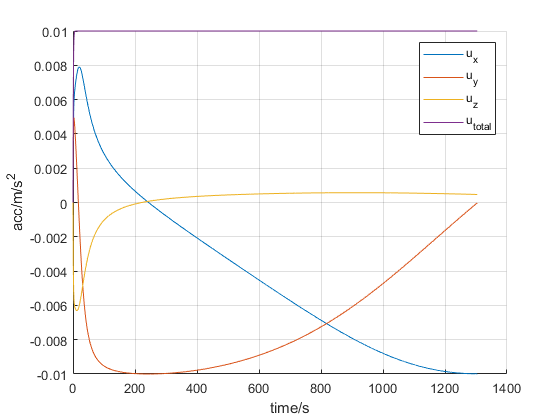

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 燃料最优（同伦）

@CostFuel: $\int \|{\bf{u}}\| \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    5.453376e-03    1.217e+04    1.110e-16
    1      14    8.198748e-02    4.628e+01    6.329e+05    2.092e+02
    2      21    8.503417e-02    6.369e+00    1.061e+05    4.140e+00
    3      28    8.518323e-02    7.578e-03    3.021e+02    2.299e-01
    4      35    8.518314e-02    5.460e-09    5.809e+00    1.257e-04

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the 

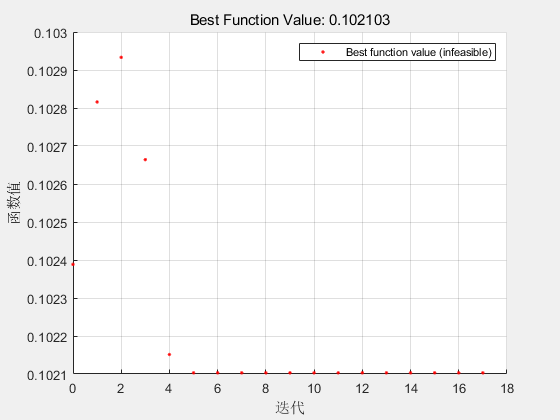


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



[s,fval,exitflag,output] = IndirOptFuel(@CwFuelOpt, x0, xf, tf, p);

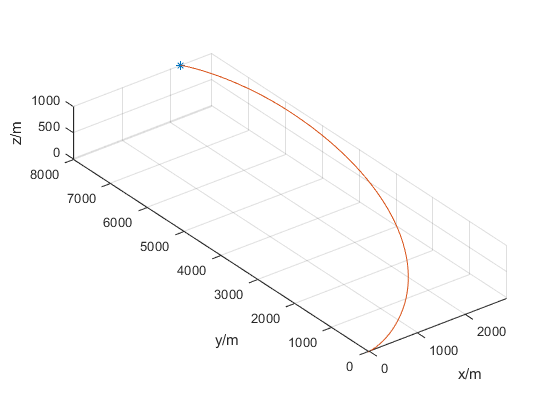

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

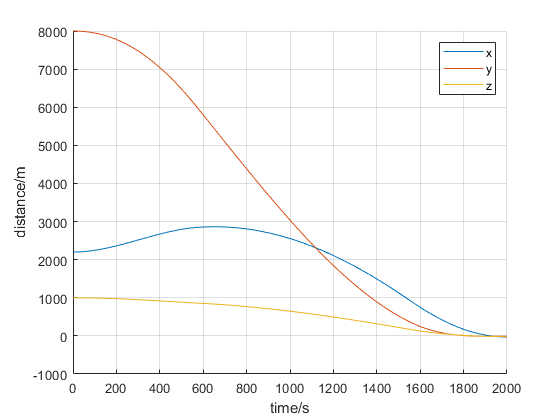

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

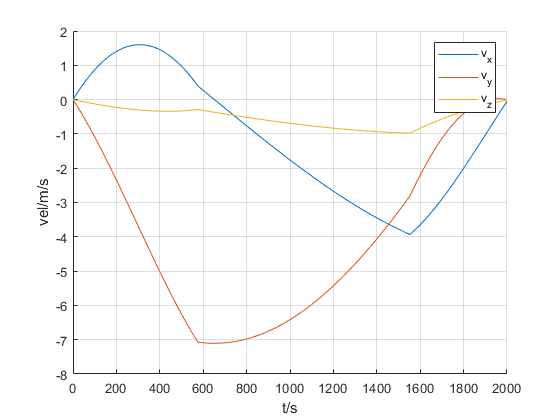

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

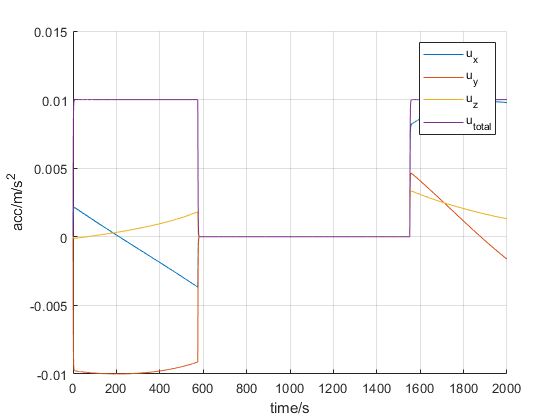

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off